# [Example 2.4] 

# x(n) = u(n) - u(n-10)을 가정하자. x(n)을 우함수 성분과 기함수 성분으로 분해하라.

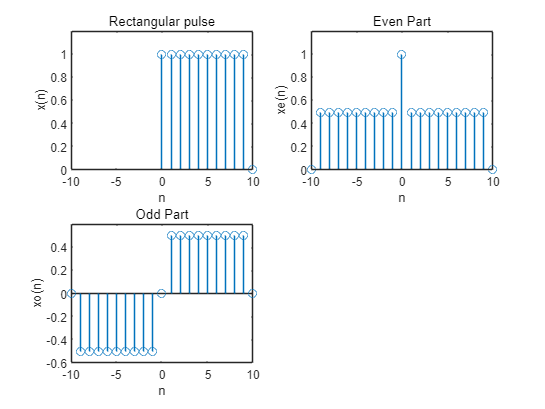

n = 0:10;   x = stepseq(0,0,10) - stepseq(10,0,10);
[xe, xo, m] = evenodd(x,n);

subplot(2,2,1); stem(n,x); title('Rectangular pulse');
xlabel('n'); ylabel('x(n)'); axis([-10, 10, 0, 1.2]);

subplot(2,2,2); stem(m,xe); title('Even Part');
xlabel('n'); ylabel('xe(n)'); axis([-10, 10, 0, 1.2]);

subplot(2,2,3); stem(m,xo); title('Odd Part');
xlabel('n'); ylabel('xo(n)'); axis([-10, 10, -0.6, 0.6]);